# IMPORT DATA

close all
clc
clear all

dir = pwd;
wind_data = readtable(strcat(dir, '\Data\Wind_data.csv')).WindSpeed_m_s_;    %already access the table

Remove NaN from data

wind_data = wind_data(~isnan(wind_data));

Turbine data

rho_air = 1.225;            % air density [kg/m3]
H = 119;                    % hub height [m]
R_rotor = 178.3/2;               % rotor radius [m]
A_rotor = pi*R_rotor^2;     % rotor area [m2]
V_rated = 11.4;               % rated wind speed [m/s]
V_ci = 4;                   % cut-in wind speed [m/s]
V_co = 25;
Jeq = 1.56e8;                % equivalent inertia [kg*m2]
b = 2e5;                  % damping (equivalent losses) coefficient [N*m*s/rad]
P_rated = 10e6;             % rated power [W]
pole_pairs = 320;           % poles pairs
magnets_flux = 19.49;       % magnets flux [Wb]
stat_resistance = 64e-3;    % stator resistance [ohm]



Calculate wind significant speeds.

We will consider the following quantiles:

0.25, 0.5, 0.75

significant_speed_1 = quantile(wind_data, 0.25);  % 25 per cent of wind speeds
significant_speed_2 = quantile(wind_data, 0.5);
significant_speed_3 = quantile(wind_data, 0.75);
significant_speed_mean = mean(wind_data);

Calculate the 3 kaimal spectrums

freq = linspace(0, 100, 1000);
S_1 = (0.1^2 * significant_speed_1 * 600) ./ ((1+ 1.5.*((freq*600)./significant_speed_1)).^(5/3));
S_2 = (0.1^2 * significant_speed_2 * 600) ./ ((1+ 1.5.*((freq*600)./significant_speed_2)).^(5/3));
S_3 = (0.1^2 * significant_speed_3 * 600) ./ ((1+ 1.5.*((freq*600)./significant_speed_3)).^(5/3));
S_mean = (0.1^2 * significant_speed_mean * 600) ./ ((1+ 1.5.*((freq*600)./significant_speed_mean)).^(5/3));

Plots

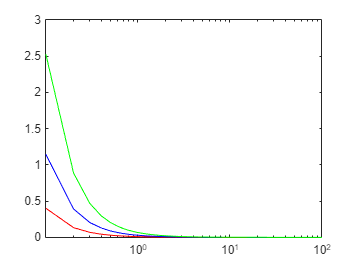

plot(freq, S_1, 'Color','r')
xscale log
xlim([0, 100])
hold on
plot(freq, S_2, 'Color','b')
plot(freq, S_3, 'Color','g')
hold off

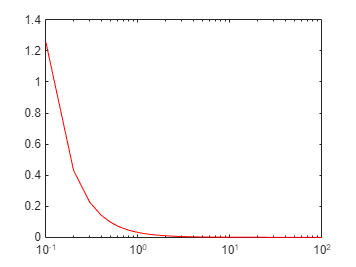



plot(freq, S_mean, 'Color','r')
xscale log